% header

# Root of a quadratic equation

## Part 1: Single analysis

One of the solutions (roots) to the equation $Ax^2 +\textrm{Bx}+C=0$ can be found by iteratively solving the rearranged equation$x=-\frac{B}{A}-\frac{C}{\textrm{Ax}}$ .

- Use a looping structure to iteratively solve the above equation when `A`, `B`, and `C` have values of **1.2**, **-2.8**, and **0.8**, respectively. 

- Use **1 **as an initial guess of `x`. 

- The iterative process may stop when the absolute percent difference between subsequent estimates of `x` is less than **0.01%**.

- Store the final approximation of the root as the variable `result` and the number of iterations as the variable `iter`.

- *After 7 iterations, the result will be equal to 2.* 

% Part 1 code
clc;clear;

A=1.2;
B=-2.8;
C=.8;
x=1;
xi=-B/A-C/A/x;
iter=0;
while abs(x-xi)/xi>=.0001
    xi=x;
    x=-B/A-C/A/xi;
    iter=iter+1;
end
disp(x)

    2.0000



disp(xi)

    1.9999



disp(iter)

     7




Quad1=-B+sqrt(B^2-4*A*C)/2/A

Quad1 = 3.6333

Quad2=-B-sqrt(B^2-4*A*C)/2/A

Quad2 = 1.9667

## Part 2: Multiple Analyses

The table array, `T`, contains the coefficients `A`, `B`, and `C` for multiple quadratic equations.

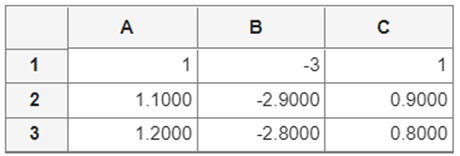

Each row of the table array `T` represents a single polynomial. Apply the above iterative approach to each set of coefficients. For each analysis, 

- Use **1 **as an initial guess of `x`. 

- The iterative process may stop when the absolute percent difference between subsequent estimates of `x` is less than **0.01%**.

- Store the final approximation of the root as the column (i.e., variable) `X` and the number of iterations as the column (i.e., variable) `iter` in the table array `T`. 

- The code should be general enough to allow for any number of rows in the table array `T`. 

- *Applying the above analysis, should yield the below results:*

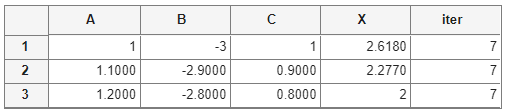

% Part 2 code
clc;clear
x=[1];
A=[1:.1:6];
A=transpose(A);
B=-3:.1:2;
B=transpose(B);
C=1:-.1:-4;
C=transpose(C);
xi=-B(1)/A(1)-C(1)/A(1)/x(1);
T=table(A,B,C)

T = 51×3 table
     A      B       C  
    ___    ____    ____

      1      -3       1
    1.1    -2.9     0.9
    1.2    -2.8     0.8
    1.3    -2.7     0.7
    1.4    -2.6     0.6
    1.5    -2.5     0.5
    1.6    -2.4     0.4
    1.7    -2.3     0.3
    1.8    -2.2     0.2
    1.9    -2.1     0.1
      2      -2       0
    2.1    -1.9    -0.1
    2.2    -1.8    -0.2
    2.3    -1.7    -0.3
    2.4    -1.6    -0.4
    2.5    -1.5    -0.5


Count=0

Count = 0

Pd=1

Pd = 1


for ii= 1:3
    iter=0
    pdif=111111
    xnew=1
    while Pd>.01
        x=xnew;
        xnew=(-T.B(ii)/T.A(ii))-(T.C(ii)/T.A(ii)*x);
        Pd=abs(x-xnew)/xnew*100;
        iter=iter+1;
    
    
    end
    T.X(ii)=xnew
    T.iter(ii)=iter
end

iter = 0

pdif = 111111

xnew = 1